dataset = load("517lab3IH_dataPart2.txt");
%dataset = sort(dataset)
XYZ = dataset(:,1:3)*1000;
V(:,1) =sqrt(sum(XYZ.^2,2));
V(:,2) = dataset(:,4)*0.001;
V= sortrows(V)

V =          0    0.7107
    2.3286    0.1123
    2.4885    0.0978
    2.6005    0.0927
    2.9307    0.0821
    2.9568    0.0807
    3.0124    0.0792
    3.1305    0.0728
    3.2249    0.0757
    3.4080    0.0778


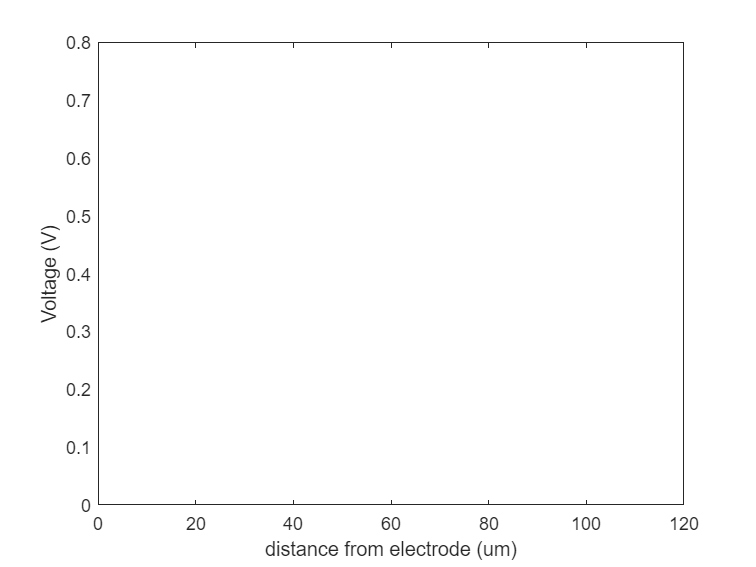

plot(V(:,1), V(:,2))
xlabel('distance from electrode (um)')
ylabel('Voltage (V)')

dataset2 = load("517lab3IH_dataPart3.txt");
V(:,1) = dataset2(:,1).* 1000;
V(:,2) = dataset2(:,4).*0.001;
V = sortrows(V);
dx = max(V(:,1)- min(V(:,1)))/length(V(:,1))

dx = 0.1122


V2 = V(:,1);
W = V(V2>0, :)

W =     0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000         0



dVd2 = diff(diff(V(:,2)))./dx^2

dVd2 =          0
         0
         0
         0
         0
         0
         0
    0.0000
   -0.0000
    0.0000


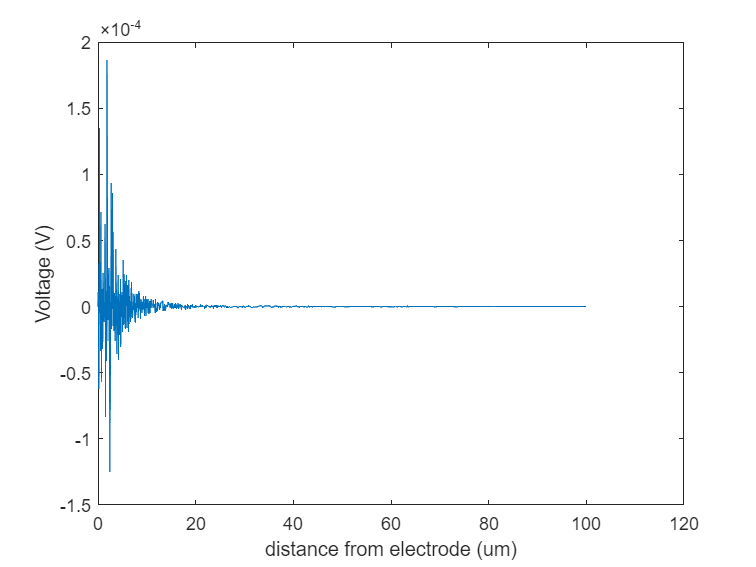

plot(W(:,1), W(:,2))
xlabel('distance from electrode (um)')
ylabel('Voltage (V)')

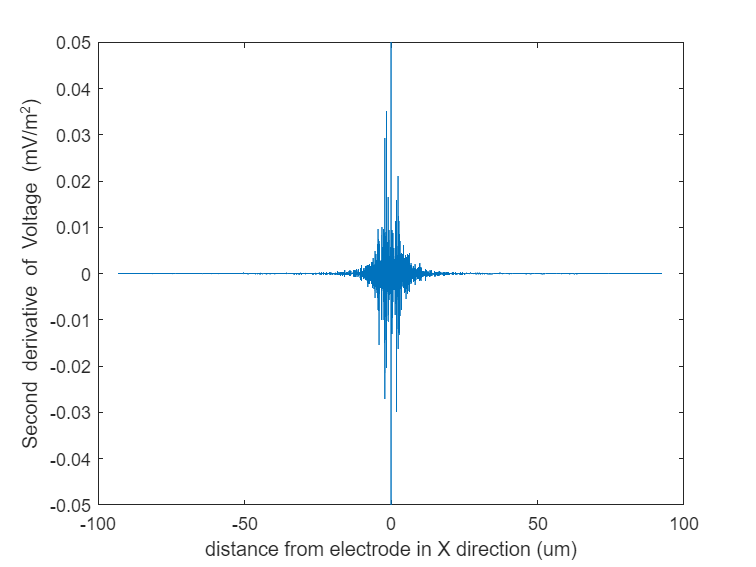

plot(V(2:1781, 1),dVd2)

xlabel("distance from electrode in X direction (um)")
ylabel("Second derivative of Voltage (mV/m^2)")
ylim([-0.05 0.05])